close all
clear all

## Specify label suffix for saving figures

suffix = '_8_9_2020';
xlimits = [0 40];

## Initialize simulation object

aplysia = AplysiaFeeding();

## Biting

disp('Biting')

Biting


aplysia = aplysia.setSensoryStates('bite');
tic
aplysia = aplysia.runSimulation();
toc

Elapsed time is 0.826786 seconds.


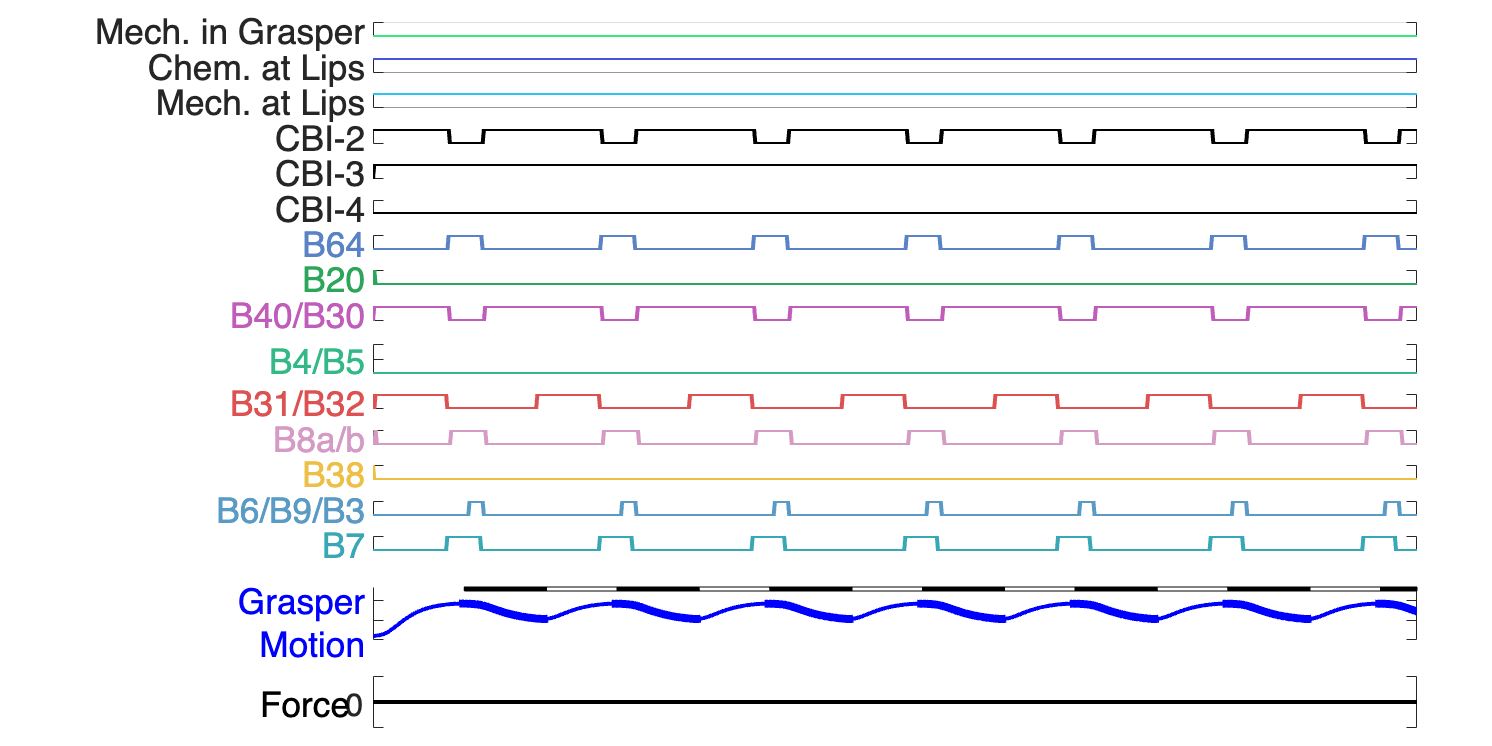

aplysia.generatePlots(['Bite_' suffix],xlimits);

## Swallowing

disp('Swallowing')

Swallowing


aplysia = aplysia.setSensoryStates('swallow');
tic
aplysia = aplysia.runSimulation();
toc

Elapsed time is 0.238246 seconds.


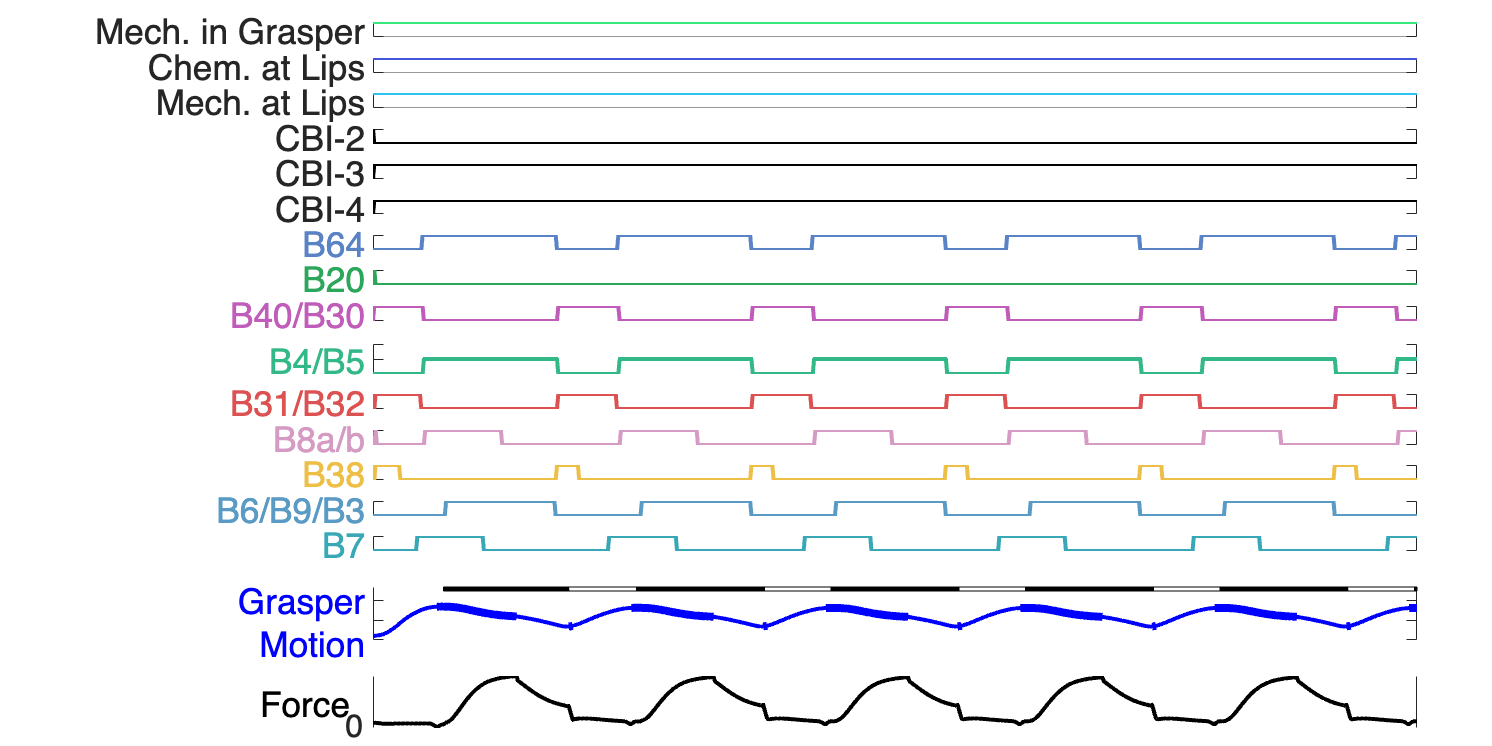

aplysia.generatePlots(['Swallow_' suffix],xlimits);

## Multifunctional swallowing of different strength seaweeds

disp('Swallowing variable strength seaweed')

Swallowing variable strength seaweed


seaweed_strength_min = 0.25;
seaweed_strength_max = 0.55;
step_size = 0.075;

seaweed_strength_vec = seaweed_strength_min:step_size:seaweed_strength_max;

num_strengths = length(seaweed_strength_vec); %round((seaweed_strength_max-seaweed_strength_min)/step_size+1);
i = 1;
t=aplysia.StartingTime:aplysia.TimeStep:aplysia.EndTime;

figure;
set(gcf,'Color','white')
for ind = 1:length(seaweed_strength_vec)
    aplysia.seaweed_strength = seaweed_strength_vec(ind);
    aplysia = aplysia.setSensoryStates('swallow');
    tic
    aplysia = aplysia.runSimulation();
    toc
    
    subplot(num_strengths,1,i)
    plot(t,aplysia.force_on_object,'k','LineWidth',2)
    hold on
    grasper_motion = (aplysia.x_g-aplysia.x_h);
    grasper_pressure = aplysia.grasper_friction_state;
    idx = grasper_pressure >=1;%pmax*0.6;
    idy = grasper_pressure <1;%pmax*0.6;
    
    grasper_motion_pressure(idx) = grasper_motion(idx);
    grasper_motion_pressure(idy)=NaN;
    
    plot(t,grasper_motion_pressure,'b','LineWidth',4)
    plot(t,grasper_motion,'b','LineWidth',2)
    hold off
    
    if i==1
        legend({'Normalized Force on Transducer','Normalized Grasper Motion'},'Orientation','horizontal','Position',[0.337905404191644,0.941469018401128,0.350331117341061,0.027292575735973],'Box','off','FontSize',12)
    end
    set(gca,'FontSize',16)
    grid on
    set(gca,'YGrid','off')
    %ylim([-2 2.1])
    xlim(xlimits)
    ylabel('Amplitude')
    set(gca,'ytick',[0 1]);
    set(gca,'YTickLabel',[0 1]);
    
    if (aplysia.seaweed_strength == seaweed_strength_min || aplysia.seaweed_strength == seaweed_strength_max)
        %Determine locations of protraction retraction boxes
        tstep = t(2)-t(1);
        startnum = xlimits(1)/tstep;
        endnum = xlimits(2)/tstep;
        grasper_rel_pos = (aplysia.x_g-aplysia.x_h);
        numProtractionBoxes = 0;
        numRetractionBoxes = 0;
        protraction = 1;
        protractionRectangles=[0,0];
        retractionRectangles=[0,0];
        for ind=startnum+2:endnum
            if grasper_rel_pos(ind) > grasper_rel_pos(ind-1)
                %protraction
                if(protraction == 0)
                    numProtractionBoxes=numProtractionBoxes+1;
                    protraction = 1;
                    %end the last retractionrectangle
                    if(numRetractionBoxes>0)
                        retractionRectangles(numRetractionBoxes,2) = ind;
                    end
                    %start a new protractionrectangle
                    protractionRectangles(numProtractionBoxes,1) = ind;
                end
            else
                %retraction
                if(protraction == 1)
                    numRetractionBoxes=numRetractionBoxes+1;
                    protraction = 0;
                    %end the last retractionrectangle
                    retractionRectangles(numRetractionBoxes,1) = ind;
                    %start a new protractionrectangle
                    if(numProtractionBoxes>0)
                        protractionRectangles(numProtractionBoxes,2) = ind;
                    end
                end
            end
        end
        
        if retractionRectangles(end,2) ==0
            retractionRectangles(end,2) = endnum;
        end
        
        if protractionRectangles(end,2) ==0
            protractionRectangles(end,2) = endnum;
        end
        
        positionAxesCell = get(gca,{'Position'});
        positionAxes = positionAxesCell{1};
        leftAxes = positionAxes(1);
        widthAxes = positionAxes(3);
        bottomAxes = positionAxes(2)+positionAxes(4);
        
        hold on
        for retract = 1:length(retractionRectangles)
            h=rectangle('Position', [retractionRectangles(retract,1)*tstep 1 (retractionRectangles(retract,2)-retractionRectangles(retract,1))*tstep 0.1]);
            h.FaceColor = 'black';
        end
        hold off
        
        hold on
        for protract = 1:length(protractionRectangles)
            h=rectangle('Position', [protractionRectangles(protract,1)*tstep 1 (protractionRectangles(protract,2)-protractionRectangles(protract,1))*tstep 0.1]);
            h.FaceColor = 'white';
        end
        hold off
    end
    
    if (aplysia.seaweed_strength ~= seaweed_strength_max)
        set(gca,'XTickLabel',[]);
    end
    i=i+1;
end

Elapsed time is 0.114916 seconds.
Elapsed time is 0.075746 seconds.
Elapsed time is 0.019186 seconds.
Elapsed time is 0.011913 seconds.
Elapsed time is 0.012020 seconds.


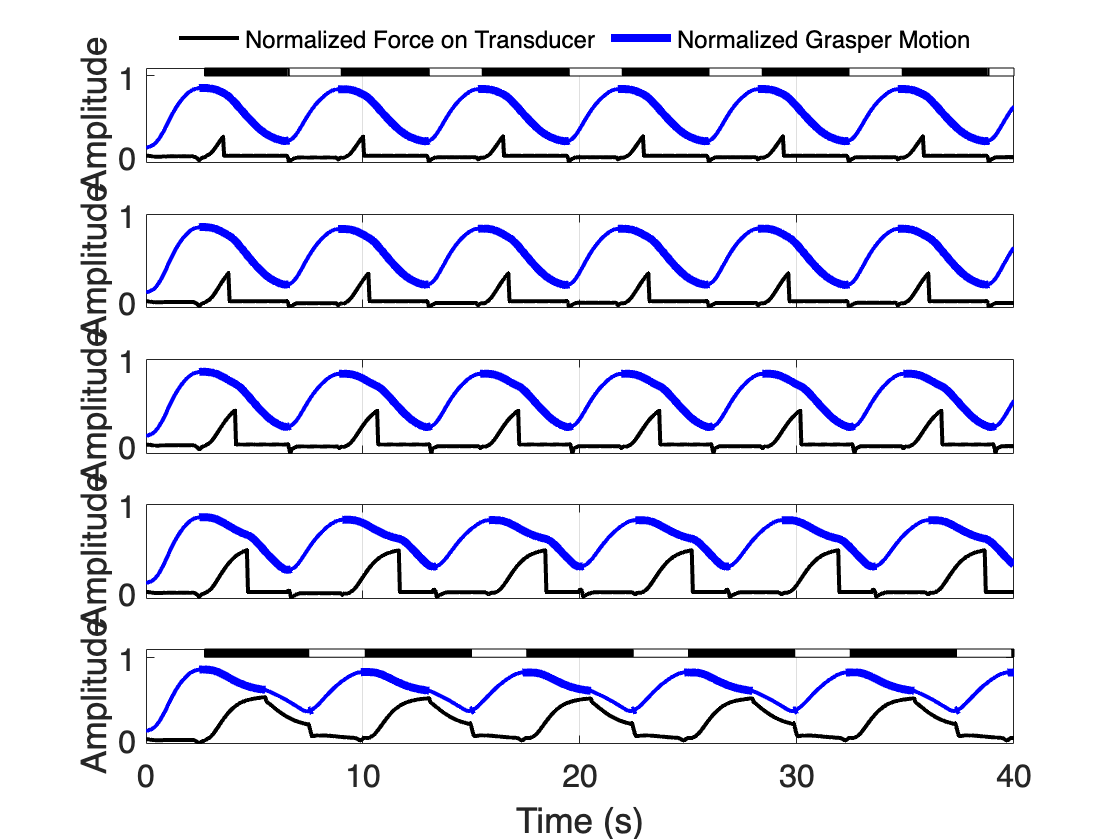

xlabel('Time (s)')
if ~exist('fig', 'dir')
    mkdir('fig');
end
saveas(gcf,['fig/' 'SeaweedStrength_' suffix '.png'])

## Rejection

disp('Rejection')

Rejection


aplysia = aplysia.setSensoryStates('reject');
tic
aplysia = aplysia.runSimulation();
toc

Elapsed time is 0.095908 seconds.


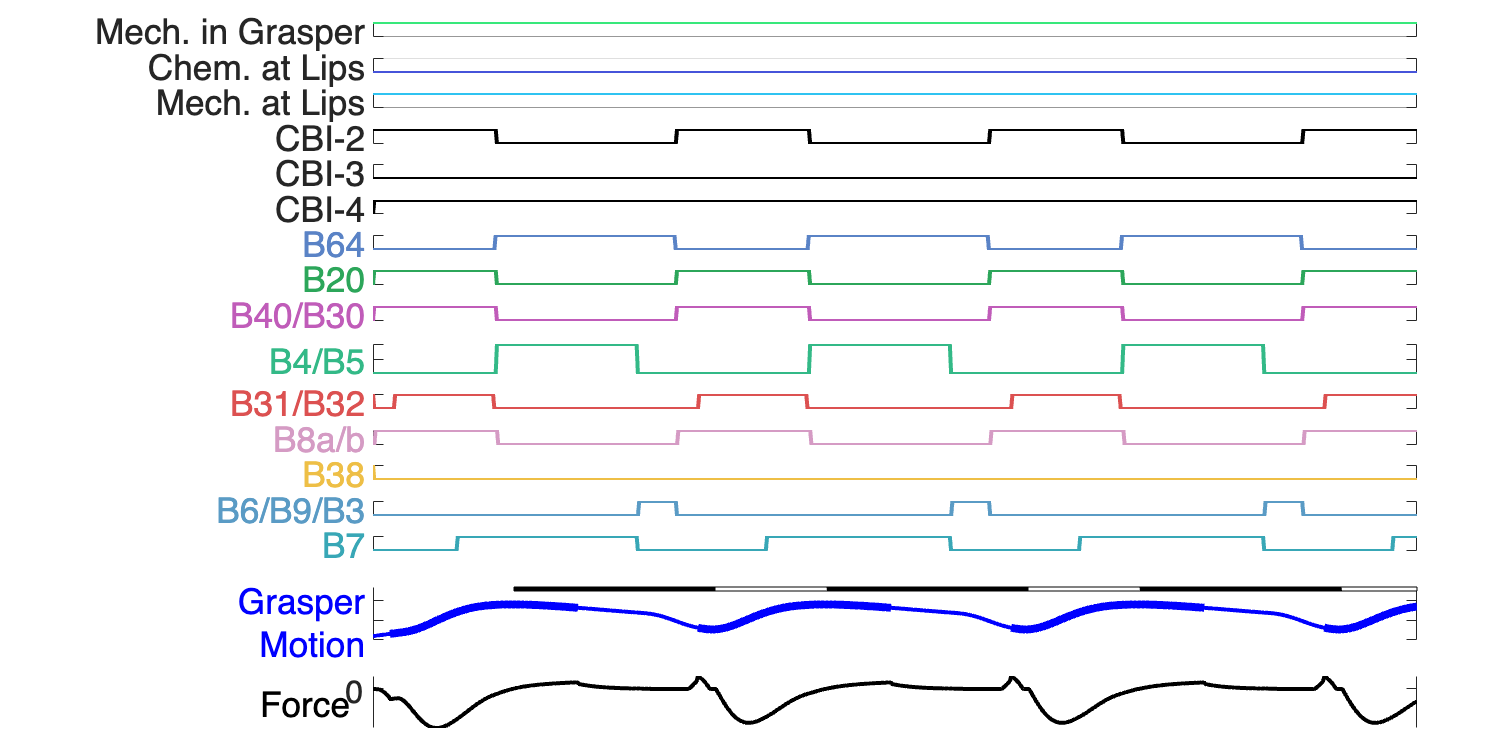

aplysia.generatePlots(['Reject' suffix],xlimits);

## Swallowing to rejection

disp('Swallow to rejection')

Swallow to rejection


t_switch = 19.95;

aplysia = aplysia.setSensoryStates('swallow','reject',t_switch);
tic
aplysia = aplysia.runSimulation();
toc

Elapsed time is 0.035164 seconds.


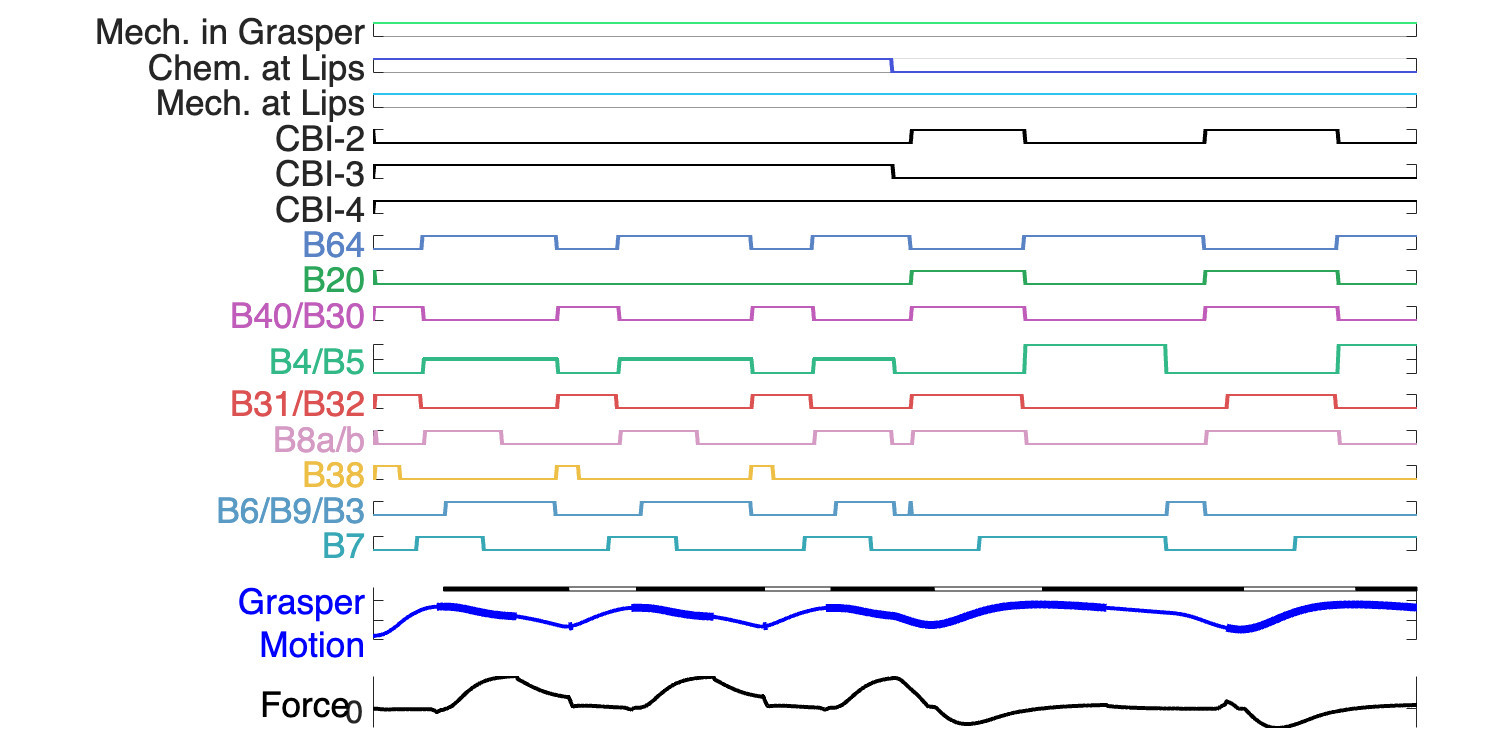

aplysia.generatePlots(['Swallow_to_reject_' suffix],xlimits);

## Biting to swallowing

disp('Biting to swallowing')

Biting to swallowing


t_switch = 19.01;
aplysia = aplysia.setSensoryStates('bite','swallow',t_switch);
tic
aplysia = aplysia.runSimulation();
toc

Elapsed time is 0.022116 seconds.


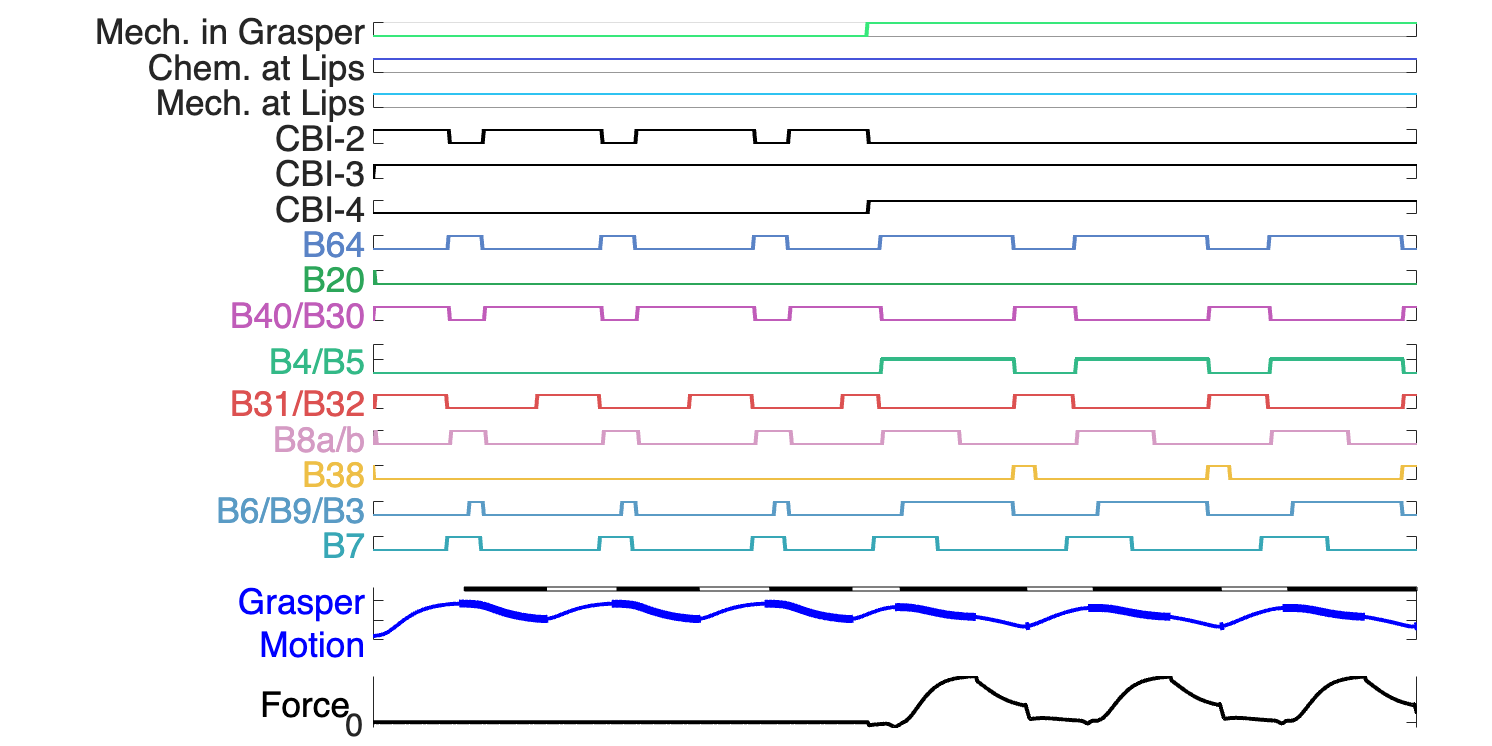

aplysia.generatePlots(['Biting_to_swallowing_' suffix],xlimits);

## B4/B5 Stimulation

aplysia.use_hypothesized_connections = 1;

t_transitionidx_1 = 250; % start stimulating B4/B5
t_transition_B4duration = 1/aplysia.TimeStep; % in timesteps
 
aplysia = aplysia.setSensoryStates('swallow');
aplysia = aplysia.setStimulationTrains('B4B5',t_transitionidx_1,t_transition_B4duration);

tic
aplysia = aplysia.runSimulation();
toc

Elapsed time is 0.059336 seconds.


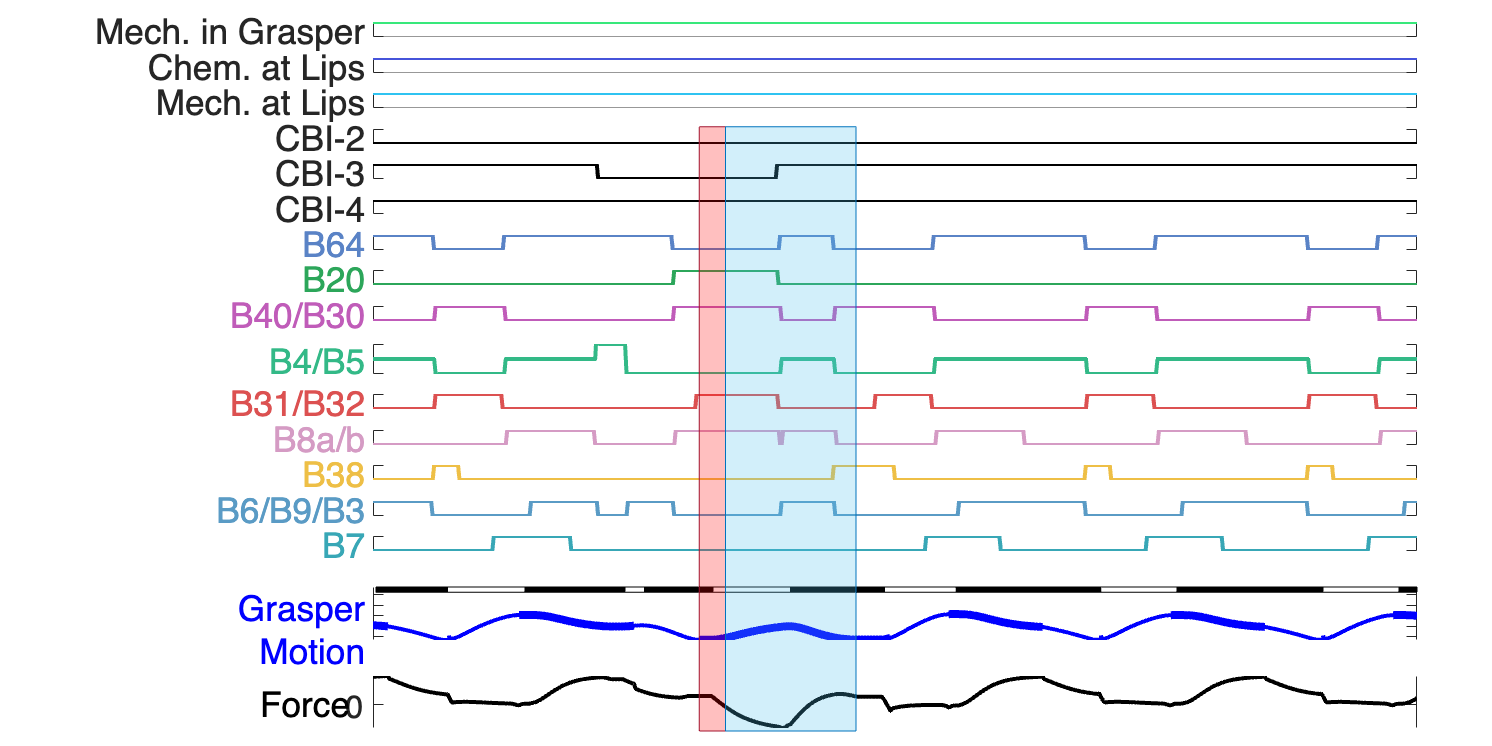


aplysia.generatePlots(['B4B5_stimulation' suffix],[5 40]);

% Create rectangle
figure1 = gcf;
totalwidth = 0.7;
totaltime = xlimits(2)-xlimits(1);
left = (t_transitionidx_1*tstep-xlimits(1))*totalwidth/totaltime+0.25;
width = t_transition_B4duration*tstep*totalwidth/totaltime;
bottom = 0.02;
height = 0.81;
annotation(figure1,'rectangle',...
    [left bottom width height],...
    'Color',[0.635294139385223 0.0784313753247261 0.184313729405403],...
    'FaceColor',[1 0 0],...
    'FaceAlpha',0.25);

% Create rectangle
CBI3_refractory_duration = aplysia.refractory_CBI3/1000/aplysia.TimeStep;
left = left+width;
width = (CBI3_refractory_duration*aplysia.TimeStep)*totalwidth/totaltime;
annotation(figure1,'rectangle',...
    [left bottom width height],...
    'Color',[0 0.450980392156863 0.741176470588235],...
    'FaceColor',[0.301960784313725 0.749019607843137 0.929411764705882],...
    'FaceAlpha',0.25);